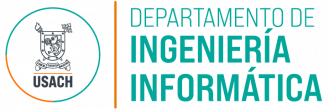

# Laboratorio 3

## PROCESAMIENTO DE SEÑALES E IMÁGENES

Unidades I y II - Análisis de señales en tiempo discreto

Martes 01/abril 15:20 hrs - EPF767

Profesores:

- Luis Corral

- Cristobal Loyola

Ayudante: Clemente Aguilar Osorio.

# Generales

 Precaución al reproducir las señales, archivos wav o sus resultados en audífonos o altavoces ya que puede ocasionar daño a su sistema de reproducción o más importante a sus oídos. 

# Contenidos 

- Frecuencia de muestreo.

- Sistemas LIT.

- Respuesta al impulso.

- Convolución.

# Resultados de aprendizaje

- Operar sobre señales de largo finito.

- Operar sobre señales de respuesta al impulso.

- Obtener la convolución de múltiples señales.

# Actividades antes de la clase

- **Actividad 0a:** repasar contenido de s1-cat1, s1-cat2, s2-cat1 y s2-cat2.

# Actividades durante de la clase

- **Actividad 1**: descarga el zip con el archivo **mlx** y otros adicionales.

- **Actividad 2**: sesión práctica en MATLAB (revisar/ejecutar/entender scripts descargados).

- **Actividad 3**: implementación de ejercicios en MATLAB.

# Actividades

Una estación de audio digital (DAW por sus siglas digital audio workstation) es un software utilizado principalmente para la producción de audio profesional. Esto le permite operar sobre secuencias de largo finito, aplicar efectos, sumar y multiplicar por escalares, entre otras muchas funciones. Una tarea general consiste en mezclar distintas grabaciones sincronizadas para generar una pieza musical de dos canales de salida (sonido estéreo). Una versión simple del proceso de mezcla consiste en sumar las señales estéreo y las monofónicas (de solo un canal) a cada salida (usualmente denominada L y R por la denominación en ingles left and rigth o izquierdo y derecho) como se muestra en la Figura 1.

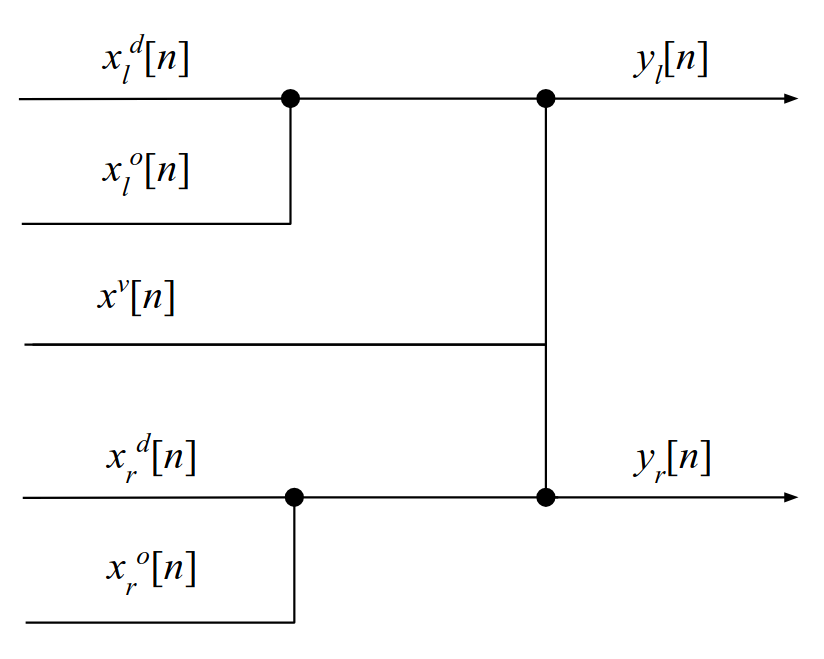

**Figura 1.** Suma de canales estéreo y monofónicos.

De forma matemática las señales de salida $y_l[n]$, $y_r[n]$ se determinan por las relaciones:


$$y_l[n] = x^d_l[n] + x^o_l[n] + x^v[n]$$



$$y_r[n] = x^d_r[n] + x^o_r[n] + x^v[n]$$


donde $x^d_l[n]$, $x^d_r[n]$corresponden a la grabación de una batería estéreo, $x^o_l[n]$, $x^o_r[n]$ corresponden a la grabación de un órgano Hammond estéreo y $x^v[n]$ corresponde a la grabación de una voz monofónica. La versión mejorada de la mezcla corresponde a la aplicación de efectos a las señales mediante la convolución con respuestas al impulso de sistemas LIT en conjunto la suma de señales, como se muestra en la Figura 2.

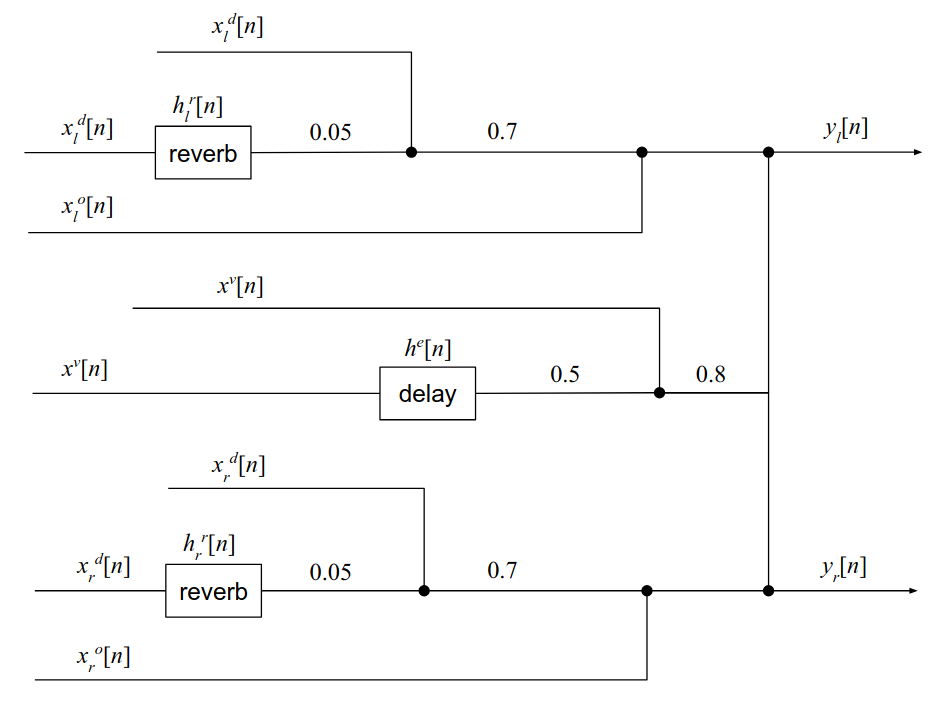

**Figura 2.** Suma de canales estéreo y monofónicos y efectos mediante convolución.

En este caso delay y reverb corresponden a sistemas LIT. La forma matemática las señales de salida $y_l[n]$, $y_r[n]$ se determinan por las relaciones:


$$y_l[n] = 0.7(0.05(x^d_l[n] * h^r_l[n]) + x^d_l[n])  + x^o_l[n] + 0.8(0.5(x^v[n] * h^e[n]) + x^v[n]) $$



$$y_r[n] = 0.7(0.05(x^d_r[n] * h^r_r[n]) + x^d_r[n])  + x^o_r[n] + 0.8(0.5(x^v[n] * h^e[n]) + x^v[n]) $$


donde $h^r_l[n]$, $h^r_r[n]$ corresponden a la respuesta al impulso estéreo del sistema reverb y $h^e[n]$ corresponde a la respuesta al impulso monofónica del sistema delay.

Los archivos **drums.wav**, **organ.wav** y **vox.wav **corresponden a $x^d_l[n]$ $x^d_r[n]$, $x^o_l[n]$ $x^o_r[n]$ y $x^v[n]$ respectivamente, mientras que los archivos **reverb.wav**, y **delay.wav **corresponden a $h^r_l[n]$ $h^r_r[n]$ y $h^e[n]$. Obtenga las señales de salida con ambas versiones del proceso de mezcla. Recuerde que la convolución con la funcion **conv()** corresponde a la suma de convolución circular, por lo que entrega señales de largo finito de $N = N_1 + N_2 -1$ muestras, donde $N_1$ es el largo de la señal $x[n$] y $N_2$ es el largo de la señal $h[n]$ en la relación ${x[n] * h[n]}$. Se considera la región central de la convolución de largo $N_1$ con el parámetro **'same'** de la función **conv()**. Puede escuchar sus resultados con la función **audioplayer()**.

[v,fs] = audioread('vox.wav');

player = audioplayer(v,fs);
play(player)
pause(15) % Segundos de reproducción.
stop(player)

# Referencias

[1] Oppenheim, A.V. & Willsky, A.S. & Nawab, S.H. (1997). Señales y sistemas (2nd ed.). Prentice Hall.

[2] [http://www.cksde.com/p_6_250.htm](http://www.cksde.com/p_6_250.htm)

[3] [https://cambridge-mt.com/ms/mtk/](https://cambridge-mt.com/ms/mtk/)